# Instantaneous Compacting Column

set_demo_defaults;

Here we consider the simplest non-trivial solution for the instantaneous compaction problem. Consider a column of hight $H$ with uniform porosity $\phi_0$ that is closed at both the top and the bottom. 

For now we are just interested in the instantaneous solution for the flow problem. Choosing the compaction length, $\delta=x_c=\sqrt{k_c\xi_c/\mu_f}$, and the initial porosity, $\phi_c = \phi_0
$, as characteristic scales the dimensionless flow problem simplifies to

1) $-\nabla_D^2h_D+h_D = z_D$,

2) $-\nabla_D^2u_D=h_D-z_D$.

These equations are linear and second depends on the solution of the first. We are interested in a one-dimensional solution so that we have to solve the following ODE's

1) $-\frac{\mbox{d}^2h_D}{\mbox{d}z_D^2}+h_D=z_D$    on  $z_D \in\left[0,\,H_D\right]$

2) $-\frac{\mbox{d}^2u_D}{\mbox{d}z_D^2} = h_D-z_D$    on  $z_D \in\left[0,\,H_D\right]$

where $H_D=H/\delta$ is the dimensionles domain height. The boundary conditions are no flow for both the solid and the melt:

$\left.\frac{\mbox{d}h_D}{\mbox{d}z_D}\right|_0=\left.\frac{\mbox{d}h_D}{\mbox{d}z_D}\right|_{H_D}=0$   and     $\left.\frac{\mbox{d}u_D}{\mbox{d}z_D}\right|_0=\left.\frac{\mbox{d}u_D}{\mbox{d}z_D}\right|_{H_D}=0$.

The only dimensionless governing parameter in this problem is the dimensionles domain height, $H_D=H/\delta$.

## Analytic solution

### Equation 1 (mod. Helmholtz)

This equation is a non-homogeneous 2nd-order equation with constant coefficients. This can be solved decomposing the solution into a homogeneous and a particular solution, $h_D = h_{D,h} + h_{D,p}$. 

The form of the homogeneous solution is determined by substituting $\mbox{e}^{rz}$ into the associated homogeneous equation. This shows that $r=\pm1$, so that the homogeneous solution takes the exponential form


$$h_{d,D} = c_1e^z + c_2e^{-z}$$


The particular solution takes the fomr of a plynominal of the same degree as the r.h.s., so that

$h_{D,p}=c_3 z_D$.

Substituting into the equations and using the boundary conditions to determine the coefficients in the homogeneous solution ($c_3=1$) we have the dimensionless solution for the overpressure head $h_D(z_D)=z+\frac{e^{-H_D}-1}{e^{H_D}-e^{-H_D}}e^z+\frac{e^{H_D}-1}{e^{H_D}-e^{-H_D}}e^{-z}$

and the associated Darcy flux, $q_D=-\frac{\mbox{d}h_D}{\mbox{d}z_D}$ is given by

$q_D(z_D) = -1-\frac{e^{-H_D}-1}{e^{H_D}-e^{-H_D}}e^z+\frac{e^{H_D}-1}{e^{H_D}-e^{-H_D}}e^{-z}$.

The dimensionless over pressure is given by $p_D = h_D-z_D$

$p_D=\frac{e^{-H_D}-1}{e^{H}-e^{-H_D}}e^z+\frac{e^{H_D}-1}{e^{H_D}-e^{-H_D}}e^{-z}$.

c1 = @(H) (exp(-H)-1)./(exp(H)-exp(-H));
c2 = @(H) (exp(H)-1)./(exp(H)-exp(-H));
hD = @(z,H) z + c1(H).*exp(z) + c2(H).*exp(-z);
qD = @(z,H) -1 - c1(H).*exp(z) + c2(H).*exp(-z);
pD = @(z,H) c1(H).*exp(z) + c2(H).*exp(-z);

### Equation 2 (Poisson)

Once the overpressure head is known we can substitute it into the r.h.s. of equation 2 to obtain

$-\nabla_D^2u_D=\frac{e^{-H_D}-1}{e^{H}-e^{-H}}e^z+\frac{e^{H_D}-1}{e^{H}-e^{-H}}e^{-z}$,

which can be solved by integrating twice. Otherwise can note that the derivatives of $u_D$ and $h_D$ are linked though the relation $v_D=-q_D$ which comes from two-phase continuity. Substituting the gradient laws we have


$$\frac{\mbox{d}h_D}{\mbox{d}z_D}=-\frac{\mbox{d}u_D}{\mbox{d}z_D}$$


which implies by integrating both sides once that $u_D = -h_D + c$, where $c$ is an arbitrary constant we set to zero. Therefore we have the following solutions for $u_D$ and $v_D$ are

$u_D(z_D)=-z-\frac{e^{-H_D}-1}{e^{H}-e^{-H}}e^z-\frac{e^{H_D}-1}{e^{H}-e^{-H}}e^{-z}$,

$v_D(z_D)=1+\frac{e^{-H_D}-1}{e^{H}-e^{-H}}e^z-\frac{e^{H_D}-1}{e^{H}-e^{-H}}e^{-z}$.

uD = @(z,H) -z - c1(H).*exp(z) - c2(H).*exp(-z);
vD = @(z,H) 1 + c1(H).*exp(z) - c2(H).*exp(-z);

## Plot solution for different domain heights

### Domain shorter than compaction length

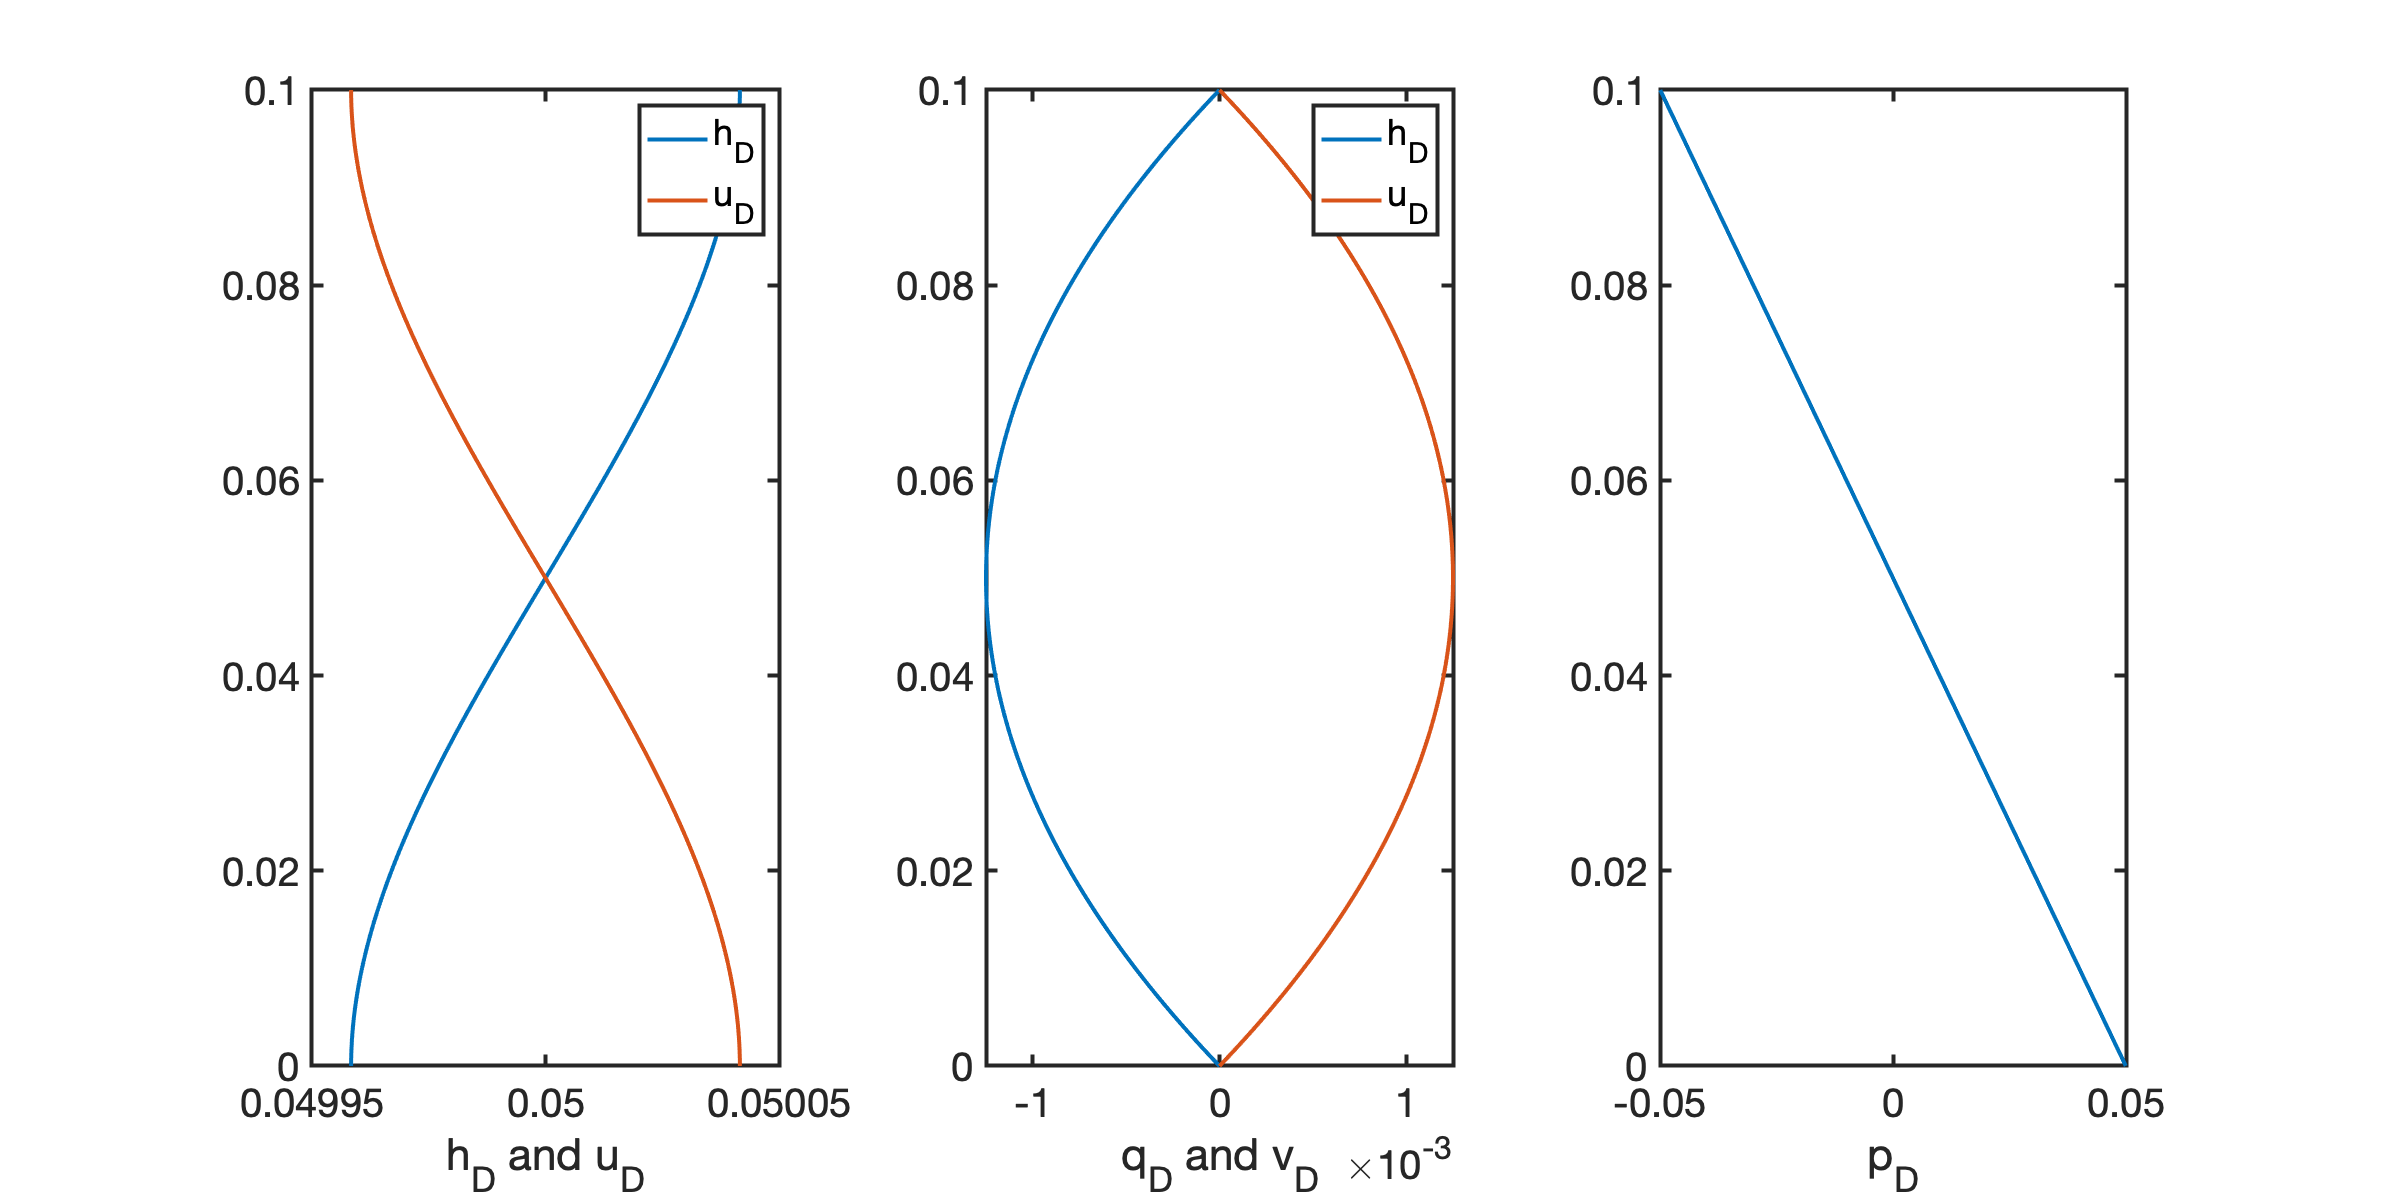

HD = 0.1;

zD = linspace(0,HD,1e3);
figure('position',[10 10 1200 600])
subplot 131
plot(hD(zD,HD),zD), hold on
plot(uD(zD,HD)+HD,zD)
legend('h_D','u_D')
set(gca,'ytick',[0:.02:.1],'fontsize',20)
xlabel('h_D and u_D')

subplot 132
plot(qD(zD,HD),zD), hold on
plot(vD(zD,HD),zD)
legend('h_D','u_D')
set(gca,'ytick',[0:.02:.1],'fontsize',20)
xlabel('q_D and v_D')

subplot 133
plot(pD(zD,HD),zD)
set(gca,'ytick',[0:.02:.1],'fontsize',20)
xlabel('p_D')

### Domain comparable to compaction length

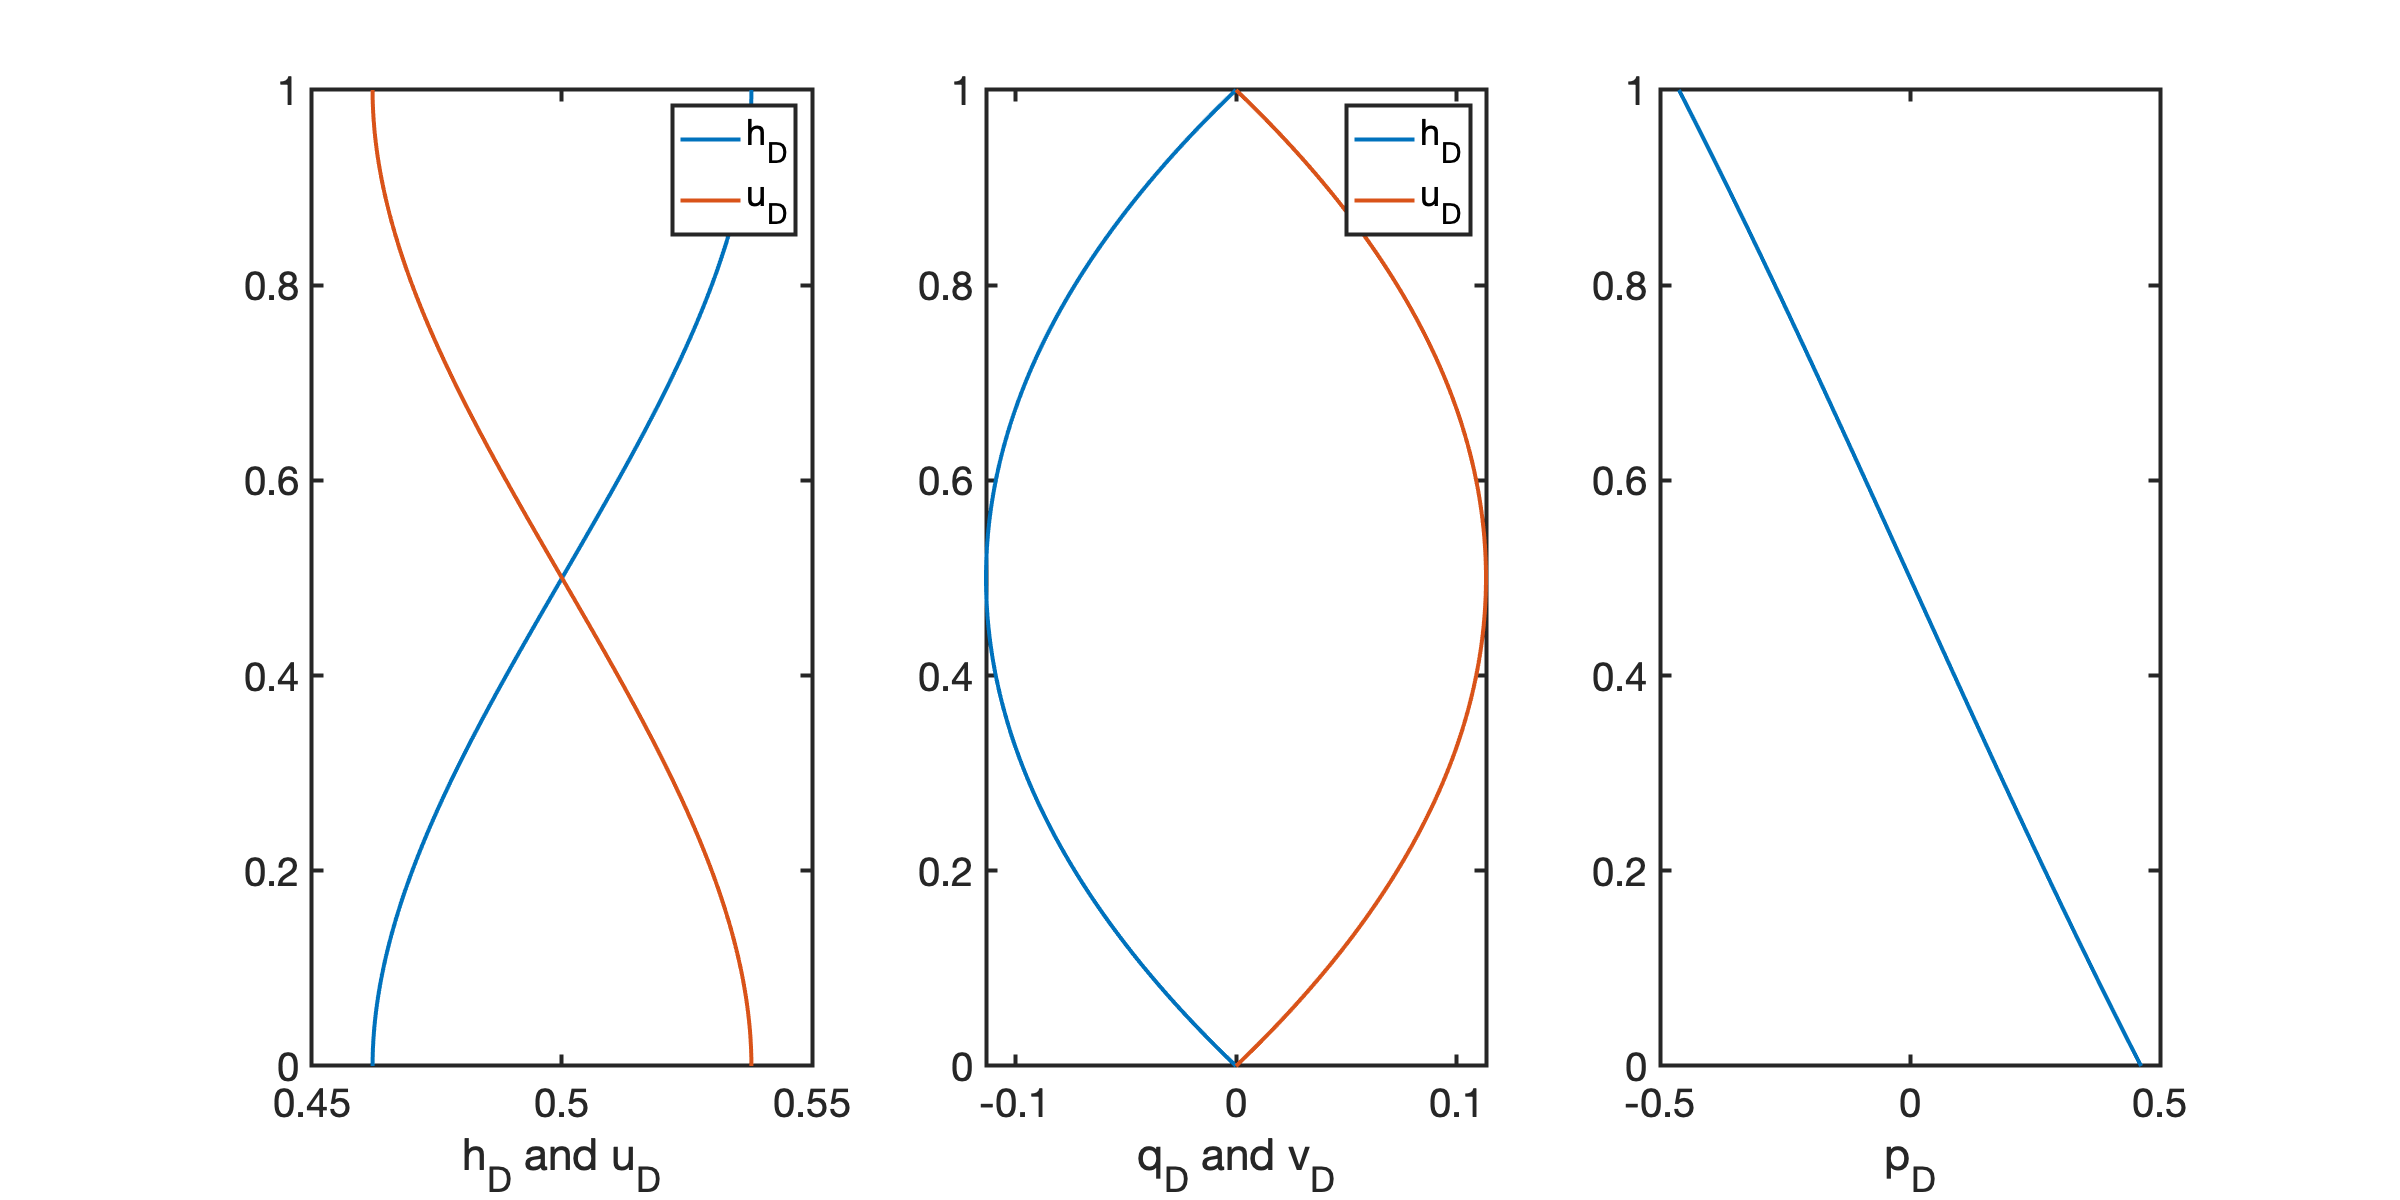

HD = 1;

zD = linspace(0,HD,1e3);
figure('position',[10 10 1200 600])
subplot 131
plot(hD(zD,HD),zD), hold on
plot(uD(zD,HD)+HD,zD)
legend('h_D','u_D')
set(gca,'ytick',[0:.2:1],'fontsize',20)
xlabel('h_D and u_D')

subplot 132
plot(qD(zD,HD),zD), hold on
plot(vD(zD,HD),zD)
legend('h_D','u_D')
set(gca,'ytick',[0:.2:1],'fontsize',20)
xlabel('q_D and v_D')

subplot 133
plot(pD(zD,HD),zD)
set(gca,'ytick',[0:.2:1],'fontsize',20)
xlabel('p_D')

Note that the magnitude of the dimensionless fluid flux and the solid velocity have increase by almost an order of magnitude. The fluid overpressure is close to linear in this limit, the fluid is overpressured in the lower half of the domain and underpressured in the top half of the domain. 

### Domain larger than the compaction length

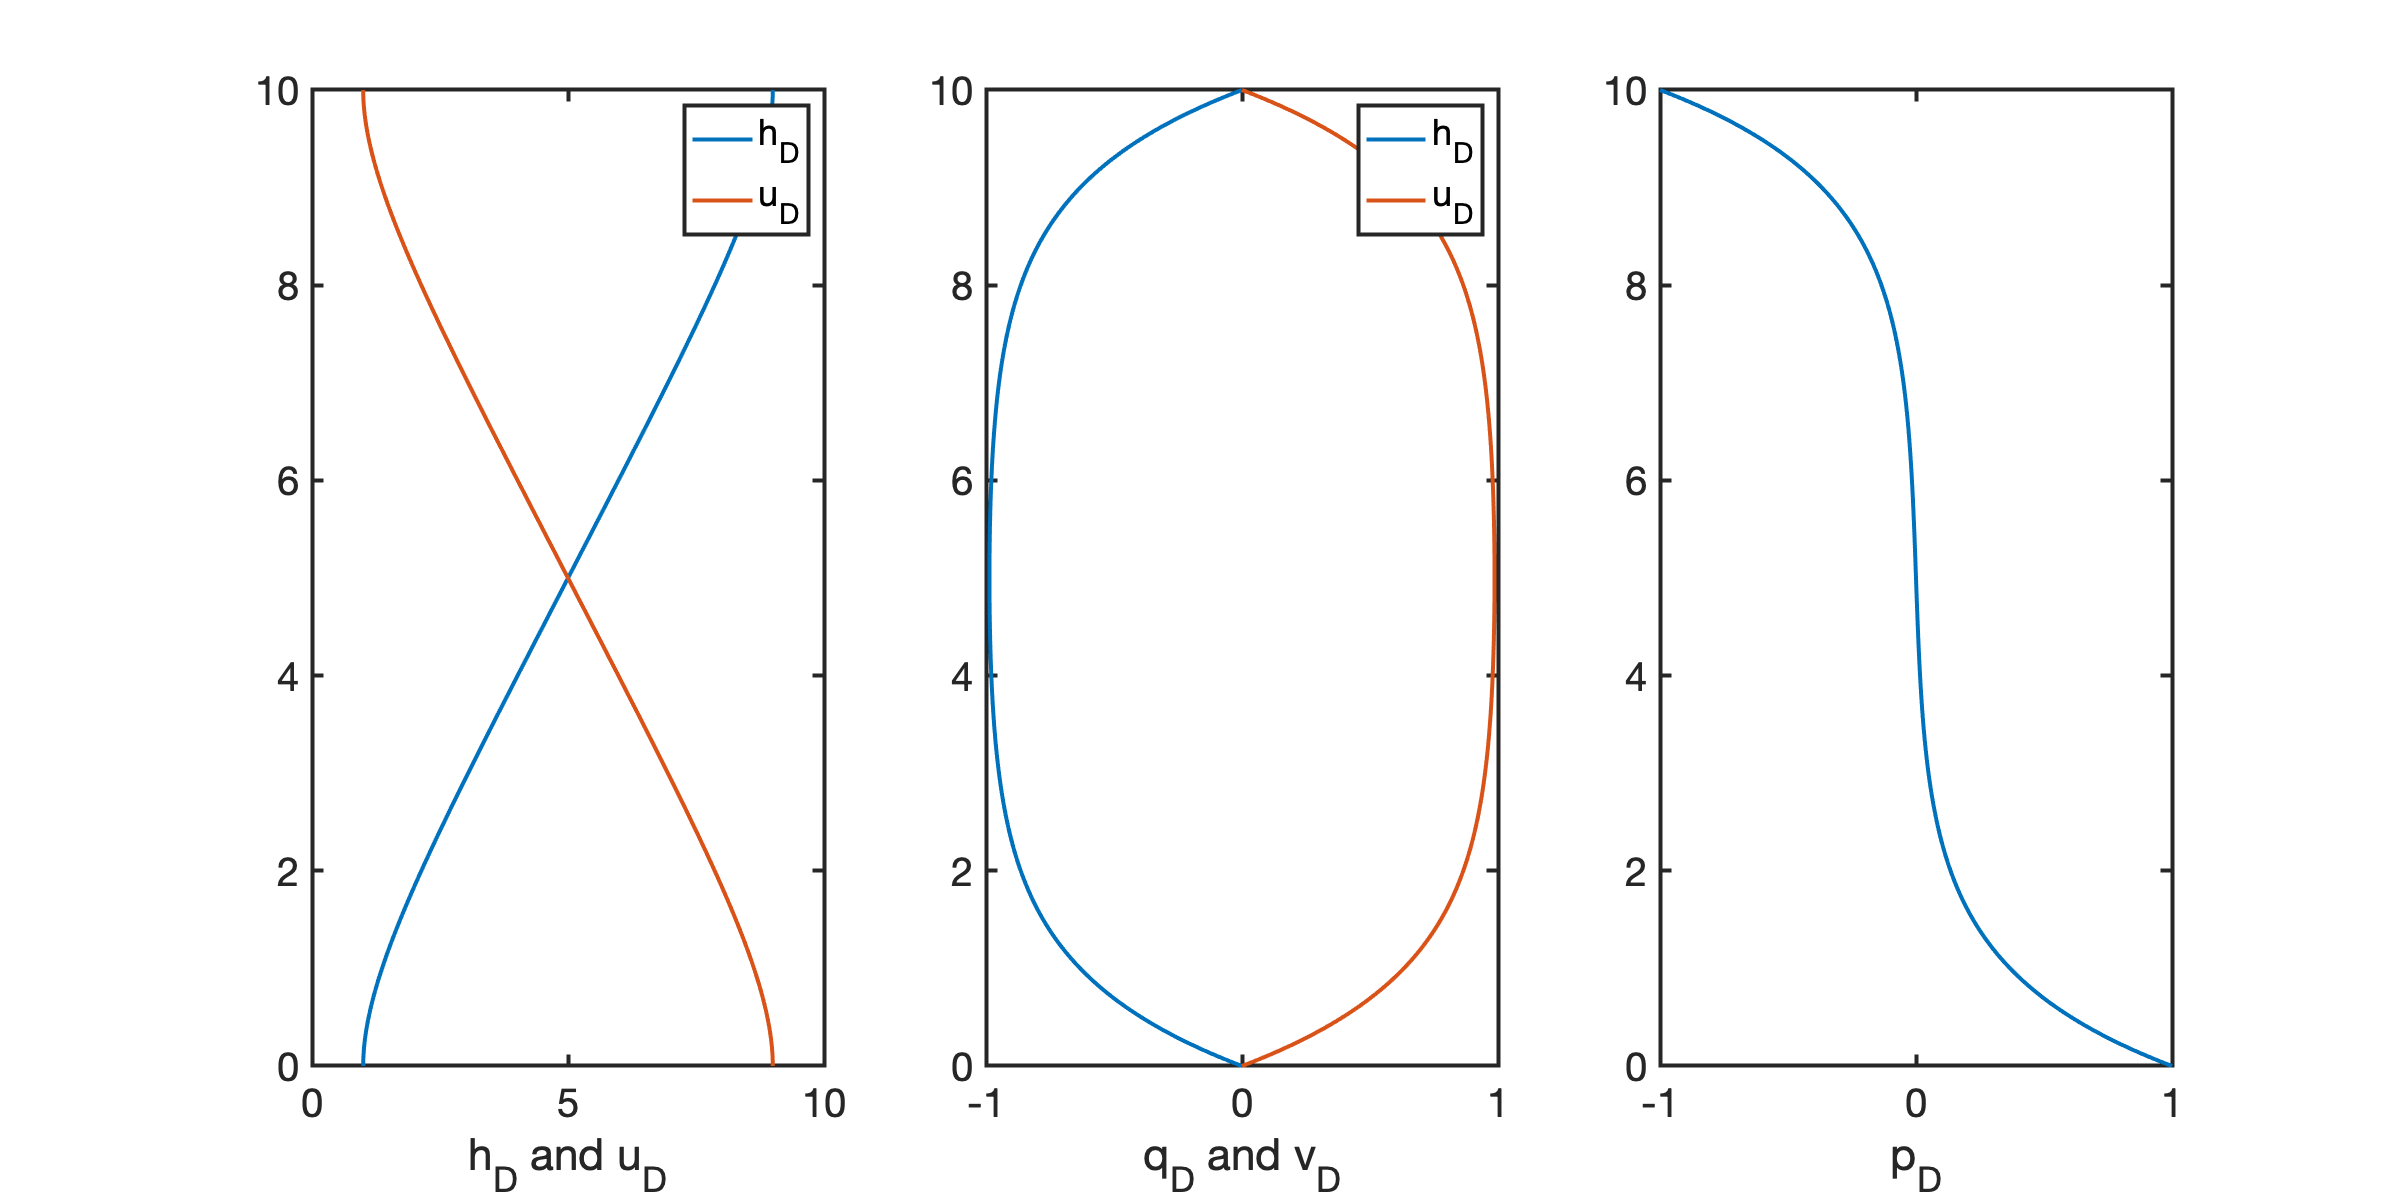

HD = 10;
Grid.xmin = 0; Grid.xmax = HD; Grid.Nx = 100;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);

zD = linspace(0,HD,1e3);
figure('position',[10 10 1200 600])
subplot 131
plot(hD(zD,HD),zD), hold on
plot(uD(zD,HD)+HD,zD)
legend('h_D','u_D')
set(gca,'ytick',[0:2:10],'fontsize',20)
xlabel('h_D and u_D')

subplot 132
plot(qD(zD,HD),zD), hold on
plot(vD(zD,HD),zD)
legend('h_D','u_D')
set(gca,'ytick',[0:2:10],'fontsize',20)
xlabel('q_D and v_D')

subplot 133
plot(pD(zD,HD),zD)
set(gca,'ytick',[0:2:10],'fontsize',20)
xlabel('p_D')

Note thet formation of a boundary layer a few compaction length thick at the top and bottom of the domain. In this boundary layer compaction/dilation accelerates/decelerates the fluid flux to/from a terminal vaue near unity in the center of the domain where the overpressure is close to zero. 

### Column much larger than compaction length

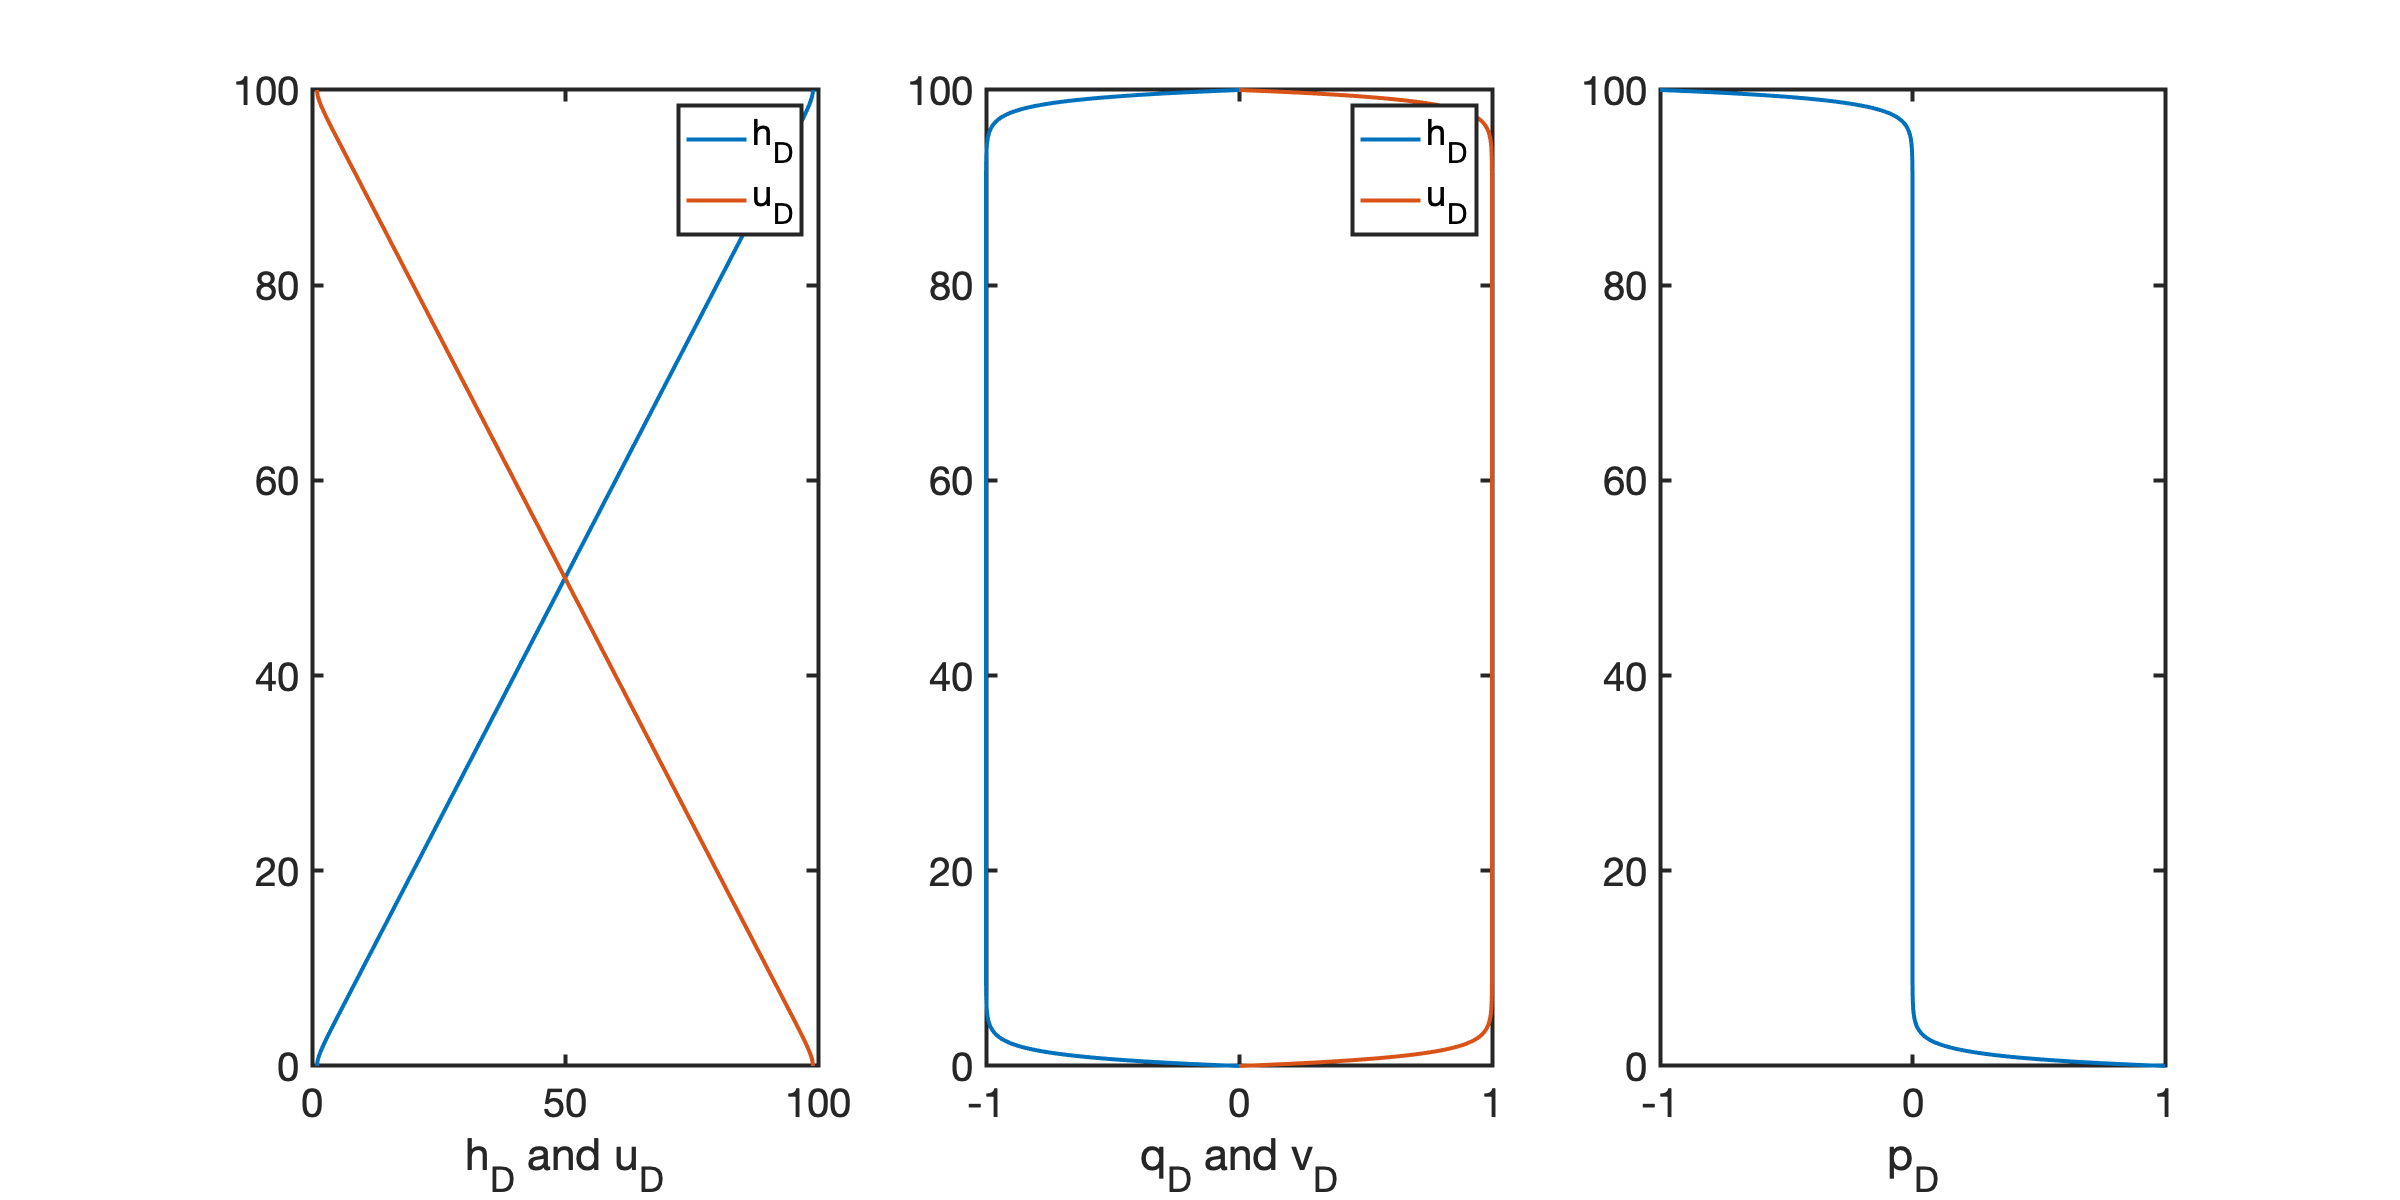

HD = 100;
Grid.xmin = 0; Grid.xmax = HD; Grid.Nx = 100;
Grid = build_grid(Grid);
[D,G,C,I,M] = build_ops(Grid);

zD = linspace(0,HD,1e3);
figure('position',[10 10 1200 600])
subplot 131
plot(hD(zD,HD),zD), hold on
plot(uD(zD,HD)+HD,zD)
legend('h_D','u_D')
set(gca,'ytick',[0:20:100],'fontsize',20)
xlabel('h_D and u_D')

subplot 132
plot(qD(zD,HD),zD), hold on
plot(vD(zD,HD),zD)
legend('h_D','u_D')
set(gca,'ytick',[0:20:100],'fontsize',20)
xlabel('q_D and v_D')

subplot 133
plot(pD(zD,HD),zD)
set(gca,'ytick',[0:20:100],'fontsize',20)
xlabel('p_D')

The formation of the boundary layer is now even clearer. The compaction length is the characteristic scale for these boundary layers and can be viewed as the correlation length of the pressure in the partially molten medium. This is a fundamental difference between a rigid (or elastic) porous medium and ductile (viscous) porous medium. In an rigid/elastic medium the stady state pressure changes communicate across the entire medium (infinite correlation length), in a ductile/viscous medium steady-state pressure changes communicate only a few compaction length.

### Dependence on qD and vD on HD

The flow velocities increase with the domain size by asymptote to 1 in the limit of very large domains. To illustrate this we can plot the maximum velocities in the center of the domain.

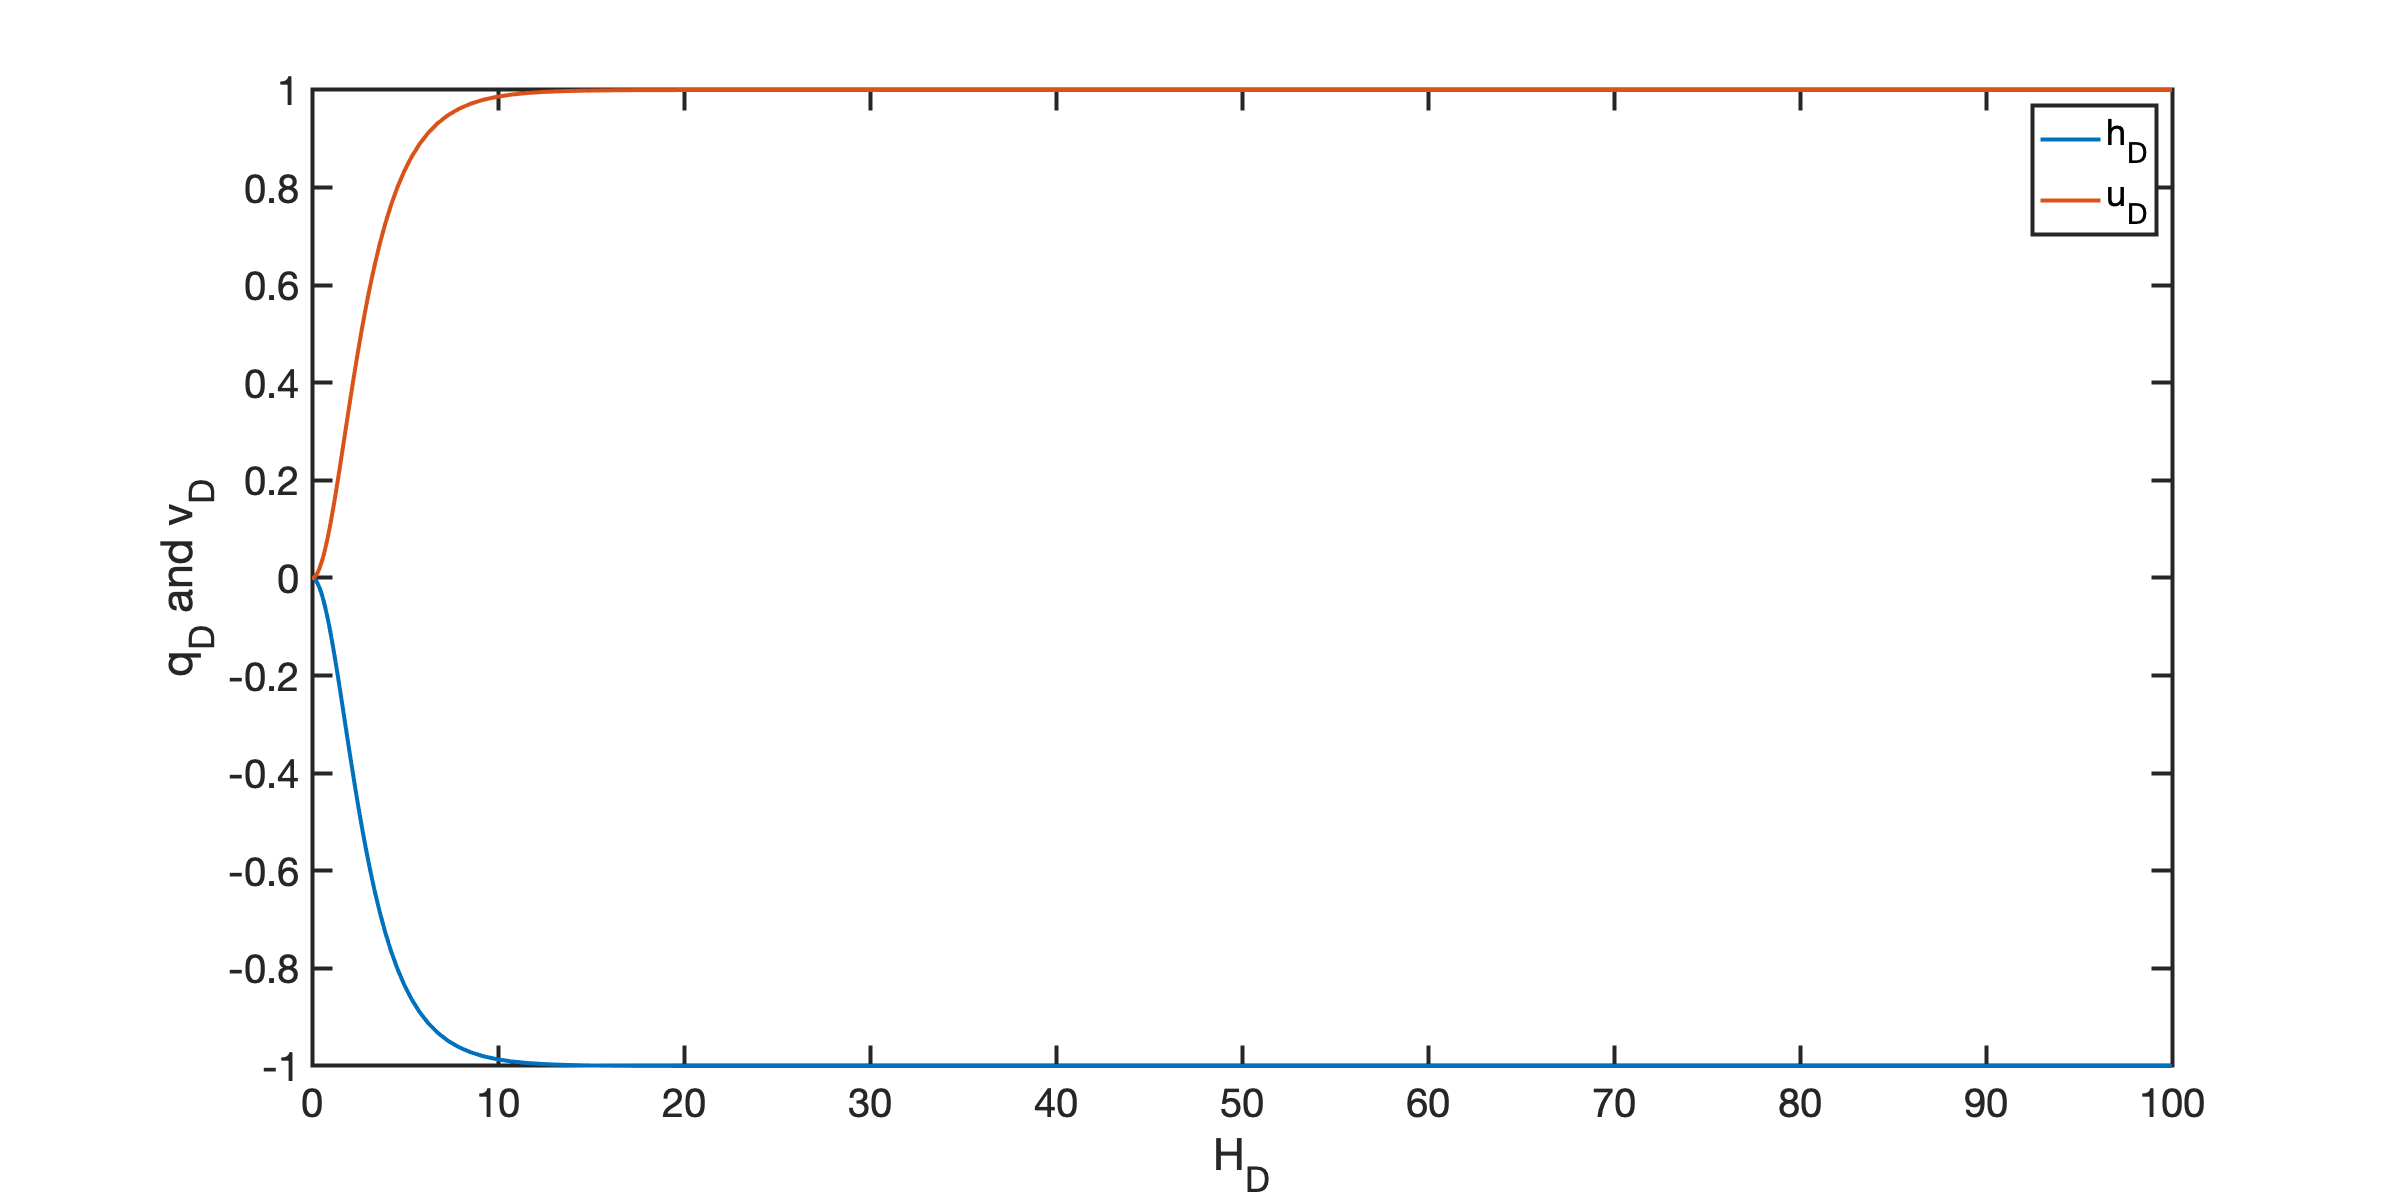

HD = logspace(-8,2,300);
figure('position',[10 10 1200 600])
plot(HD,qD(HD/2,HD)), hold on
plot(HD,vD(HD/2,HD))
legend('h_D','u_D')
xlabel('H_D')
ylabel('q_D and v_D')
set(gca,'ytick',[-1:.2:1],'fontsize',20)

Note that the terminal velocity reached by the fluid and solid are not the same! Here we are plotting the solid velocity and the fluid flux relative to it. The terminal velocities are such that the pressure gradient due to flow makes up for the difference between hydrostatic (melt) and lithostatic (solid) pressure. 